# Motion control SPLINES

Andrés Holguín Restrepo

2023-1

clear
close all

ni=9;
nf=50;


t = linspace(0,2*pi,ni);
tf=linspace(t(1),t(end),nf)

tf =              0          0.13          0.26          0.38          0.51          0.64          0.77          0.90          1.03          1.15          1.28          1.41          1.54          1.67          1.80          1.92          2.05          2.18          2.31          2.44          2.56          2.69          2.82          2.95          3.08          3.21          3.33          3.46          3.59          3.72          3.85          3.98          4.10          4.23          4.36          4.49          4.62          4.74          4.87          5.00          5.13          5.26          5.39          5.51          5.64          5.77          5.90          6.03          6.15          6.28


x = 1.5+sin(t).*exp(-t./2/pi);
y = 1.5+cos(t).*exp(-t./2/pi);
z = (2*pi-t)/2/pi+0.5;
xx=spline(t,x,tf)

xx =           1.50          1.63          1.75          1.86          1.96          2.04          2.12          2.18          2.22          2.26          2.28          2.29          2.28          2.26          2.23          2.19          2.14          2.08          2.01          1.94          1.86          1.78          1.70          1.62          1.54          1.46          1.39          1.32          1.26          1.20          1.15          1.11          1.07          1.05          1.03          1.02          1.02          1.03          1.05          1.07          1.10          1.13          1.17          1.21          1.26          1.30          1.35          1.40          1.45          1.50


yy=spline(t,y,tf)

yy =           2.50          2.47          2.43          2.37          2.30          2.22          2.14          2.04          1.94          1.84          1.73          1.63          1.53          1.43          1.33          1.25          1.17          1.10          1.03          0.98          0.94          0.91          0.89          0.89          0.89          0.90          0.92          0.95          0.99          1.04          1.09          1.14          1.20          1.26          1.33          1.39          1.45          1.51          1.57          1.63          1.68          1.72          1.76          1.80          1.83          1.85          1.87          1.88          1.88          1.87


zz=spline(t,z,tf)

zz =           1.50          1.48          1.46          1.44          1.42          1.40          1.38          1.36          1.34          1.32          1.30          1.28          1.26          1.23          1.21          1.19          1.17          1.15          1.13          1.11          1.09          1.07          1.05          1.03          1.01          0.99          0.97          0.95          0.93          0.91          0.89          0.87          0.85          0.83          0.81          0.79          0.77          0.74          0.72          0.70          0.68          0.66          0.64          0.62          0.60          0.58          0.56          0.54          0.52          0.50


format bank
data=[xx' yy' zz']

data =           1.50          2.50          1.50
          1.63          2.47          1.48
          1.75          2.43          1.46
          1.86          2.37          1.44
          1.96          2.30          1.42
          2.04          2.22          1.40
          2.12          2.14          1.38
          2.18          2.04          1.36
          2.22          1.94          1.34
          2.26          1.84          1.32


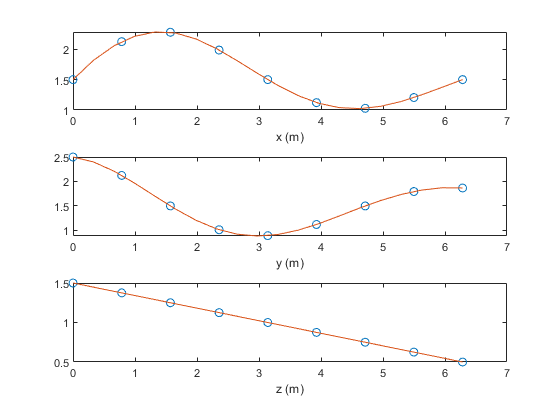


figure()

subplot(3,1,1)
plot(t,x,'o',tf,xx)
xlabel("x (m)")
subplot(3,1,2)
plot(t,y,'o',tf,yy)
xlabel("y (m)")
subplot(3,1,3)
plot(t,z,'o',tf,zz)
xlabel("z (m)")

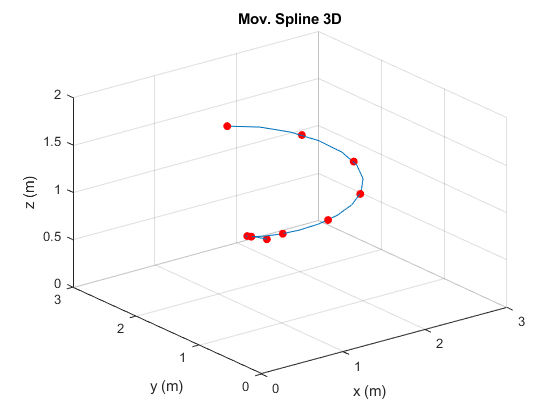


figure()
%line(x,y,z,'Color','red','LineStyle','--')
hold on
scatter3(x,y,z,'filled',"o","MarkerFaceColor","red")
line(xx,yy,zz)
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
view(120,50);
grid on
title("Mov. Spline 3D")
hold off
view(3)
axis([0 3 0 3 0 2]);

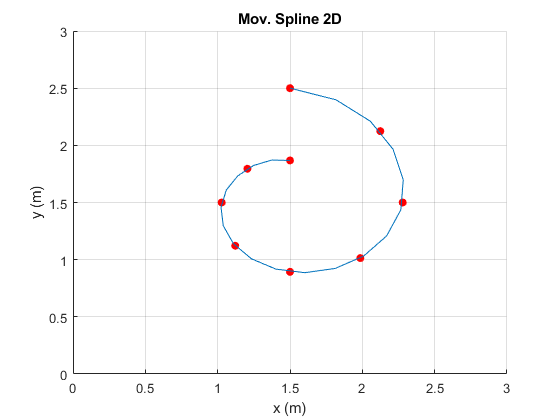

figure()
scatter(x,y,'filled',"o","MarkerFaceColor","red")
line(xx,yy)
xlabel("x (m)");
ylabel("y (m)");
axis([0 3 0 3]);
grid on
title("Mov. Spline 2D")


pp = spline(t,sqrt(x.^2+y.^2))

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.7854 1.5708 2.3562 3.1416 3.9270 4.7124 5.4978 6.2832]
     coefs: [8×4 double]
    pieces: 8
     order: 4
       dim: 1


rhoSPLINE = ppval(pp, linspace(0,2*pi,101))

rhoSPLINE =     2.9155    2.9389    2.9592    2.9765    2.9909    3.0024    3.0111    3.0171    3.0204    3.0211    3.0192    3.0149    3.0081    2.9990    2.9875    2.9738    2.9580    2.9401    2.9201    2.8981    2.8742    2.8484    2.8209    2.7916    2.7607    2.7282    2.6941    2.6586    2.6218    2.5839    2.5448    2.5049    2.4640    2.4225    2.3804    2.3377    2.2948    2.2515    2.2082    2.1649    2.1218    2.0791    2.0370    1.9958    1.9555    1.9165    1.8788    1.8427    1.8084    1.7761


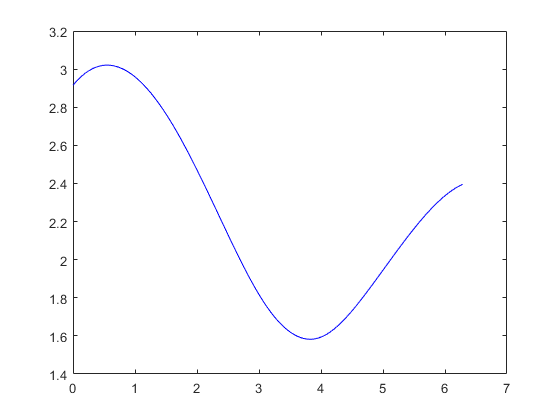

plot(linspace(0,2*pi,101),rhoSPLINE,'-b')

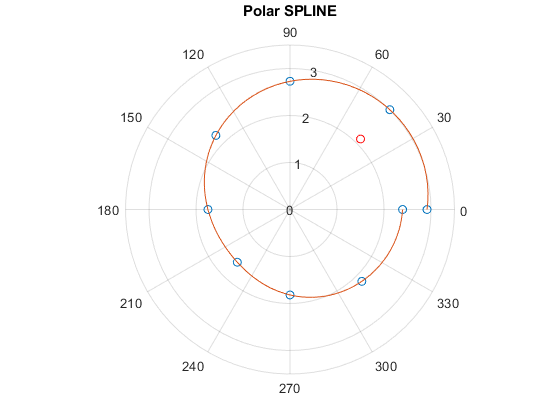

polarplot(t,sqrt(x.^2+y.^2),'o')
hold on
polarplot(linspace(0,2*pi,101),rhoSPLINE)
polarplot(pi/4,1.5*sqrt(2),'r-o')
hold off
title("Polar SPLINE")

### Tipos de interpolación

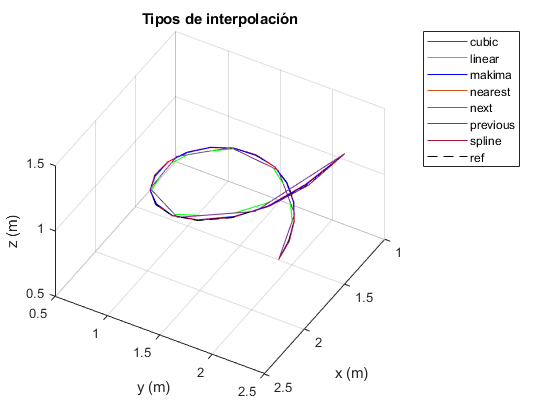

figure()
line(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"),interp1(t,z,tf,"cubic"),'Color','red','LineWidth',0.25)
hold on
line(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"),interp1(t,z,tf,"linear"),'Color','green','LineWidth',0.25)
line(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"),interp1(t,z,tf,"makima"),'Color','blue','LineWidth',0.25)
line(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"),interp1(t,z,tf,"nearest"),'Color','#D95319','LineWidth',0.25)
line(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"),interp1(t,z,tf,"next"),'Color','magenta','LineWidth',0.25)
line(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"),interp1(t,z,tf,"previous"),'Color','#7E2F8E','LineWidth',0.25)
line(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"),interp1(t,z,tf,"spline"),'Color','#A2142F','LineWidth',0.25)
plot3(1.5+sin(tf).*exp(-tf./2/pi),1.5+cos(tf).*exp(-tf./2/pi),(2*pi-tf)/2/pi+0.5,"k--")
hold off
view(120,50);
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
title("Tipos de interpolación")
legend("cubic","linear","makima","nearest","next","previous","spline","ref")
grid on

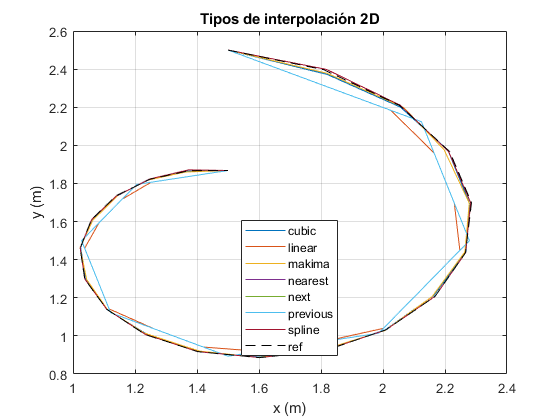


figure()
plot(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"))
hold on
plot(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"))
plot(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"))
plot(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"))
plot(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"))
plot(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"))
plot(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"))
plot(1.5+sin(tf).*exp(-tf./2/pi),1.5+cos(tf).*exp(-tf./2/pi),"k--")
hold off
xlabel("x (m)");
ylabel("y (m)");

title("Tipos de interpolación 2D")
legend("cubic","linear","makima","nearest","next","previous","spline","ref","Location","best")
%legend("cubic","spline")
grid on

## SOLUCIÓN MAYA_UN

H=3

H = 3

D=4

D = 4

delta=0.3

delta = 0.3000


[L0,L1,L2,L3,thetas]=soluciones(xx,yy,zz,H,D,delta);

## SIMULACIÓN MAYA_UN

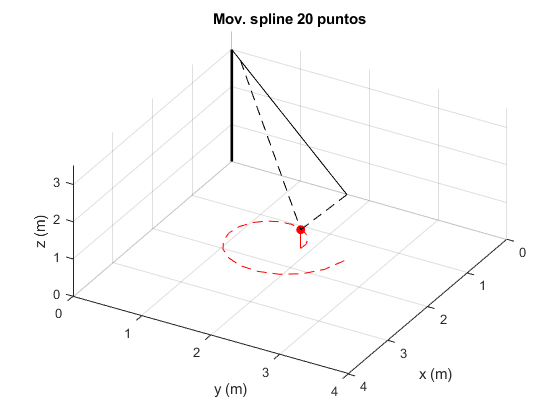

figure()
for i=1:length(xx)
    clf
    stem3(xx(i),yy(i),zz(i),"ro",'filled')
    line(xx(1:i),yy(1:i),'Color','red','LineStyle','--')
    line(L0(:,1,i),L0(:,2,i),L0(:,3,i),'Color','black','LineWidth',2)
    line(L1(:,1,i),L1(:,2,i),L1(:,3,i),'Color','black')
    line(L2(:,1,i),L2(:,2,i),L2(:,3,i),'Color','black','LineStyle','--')
    line(L3(:,1,i),L3(:,2,i),L3(:,3,i),'Color','black','LineStyle','--')
    view(120,50);
    axis([0 4 0 4 0 3.5]);
    xlabel("x (m)");
    ylabel("y (m)");
    zlabel("z (m)");
    grid on
    title("Mov. spline 20 puntos")
    %w = waitforbuttonpress;
    F(i) = getframe(gcf) ;
    drawnow
end


writerObj = VideoWriter('Caso20p',"MPEG-4");
writerObj.FrameRate = 10;

open(writerObj);

for i=1:length(F)
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
close(writerObj);

function [L0,L1,L2,L3,thetas]=soluciones(x,y,z,H,D,delta)
    for i=1:length(x)
        [L0_i,L1_i,L2_i,L3_i,thetas_i]=solMaya(x(i),y(i),z(i),H,D,delta);
        thetas(i,:)=thetas_i;
        L0(:,:,i)=L0_i;L1(:,:,i)=L1_i;
        L2(:,:,i)=L2_i;L3(:,:,i)=L3_i;
    end
end


function [L0,L1,L2,L3,thetas]=solMaya(x,y,z,H,D,delta)
    syms theta_2 theta_3
    [theta,rho,z] = cart2pol(x,y,z);
    h=z-H;
    b=sqrt((rho-delta)^2+h^2);
    c=sqrt((rho-D)^2+h^2);
    F1=0==sin(theta_3)/b-sin(theta_2)/c;
    F2=D==delta+b*cos(theta_2)+c*cos(theta_3);
    [SolTheta_2,SolTheta_3]=vpasolve([F1;F2],[theta_2;theta_3],[pi/4,pi/4]);
    SolTheta_2=-double(SolTheta_2);
    SolTheta_3=-double(SolTheta_3);
    P0=[0,0,0];
    P1=P0+[0,0,H];
    P1_2=P1+[delta,0,0]*rotz(-theta);
    P2=P1+[D,0,0]*rotz(-theta);
    P3=P1_2+[b,0,0]*roty(SolTheta_2)*rotz(-theta);
    L0=[P0;P1];L1=[P1;P2];L2=[P1_2;P3];L3=[P2;P3];
    thetas=[theta,SolTheta_2,SolTheta_3];
end

